## BIV-Übung 4

Hadi Saleh 1822230

### 1  Histogrammbasierte Segmentierung

a) 

- graythresh: input ist das 2d Bild mit einem Kanal, output is entweder T die Schwellenwert, oder [T, Em], Em ist wie effektiv die Trennung ist von 0 bis 1, 0 ist sehr schlecht und 1 sehr gut.

- imbinarize: input ist 2d oder 3d Bild mit einem Kanal, output ist das gleiche Bild aber nur mit 2 Farben für die segmentierte Hintergrund und Vordergrund. Schwellenwert wird durch Otsu-Methode gerechnet, kann aber auch als input gegeben werden.

- otsuthresh: input ist ein Histogramm, output ist die Schwellenwert. Diese Schwellenwert kann dann bei Methoden wie imbinarize benutzt werden.

- adaptthresh: benutzt Otsu **nicht**, sondern teilt das Bild in kleinere Bereiche und findet eine Schwellenwert durch eine Mittelwert-basierte statistische Methode.

Die erste drei Methoden benutzen die Otsu-Methode, die letzte nicht. graythresh findet die Schwellenwert aus einem Bild (erstellt selbst den Histogramm), otsuthresh braucht direkt einen Histogramm und kein Bild. Die Aufgabe von imbinarize ist ein binäres Bild zu erstellen, sie kann entweder die Schwellenwert mit Otsu finden oder die Schwellenwert kann als Parameter gegeben werden.

b)

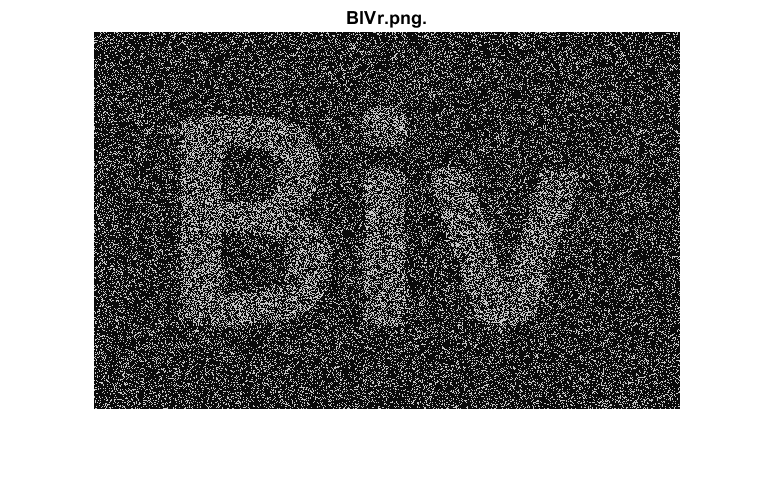

biv = imread("BIVr.png");
biv = biv(:, :, 1);
figure;
imshow(biv, [0, 255]);
title("BIVr.png.");

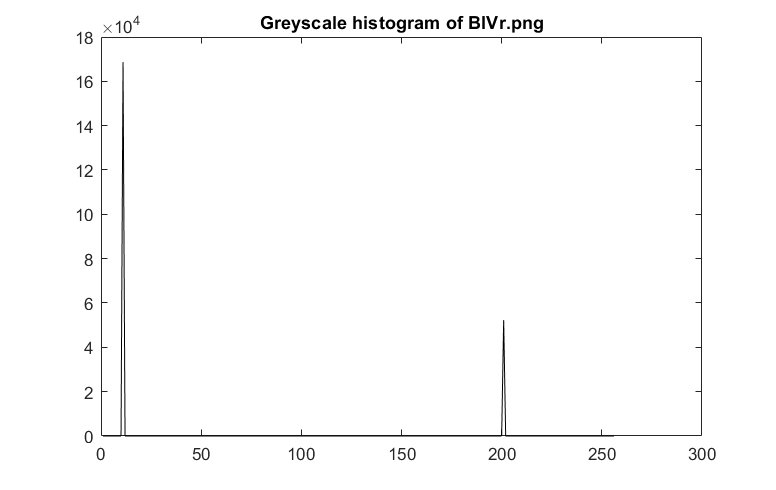

hist = imhist(biv);
plot(hist, 'k');
title("Greyscale histogram of BIVr.png");

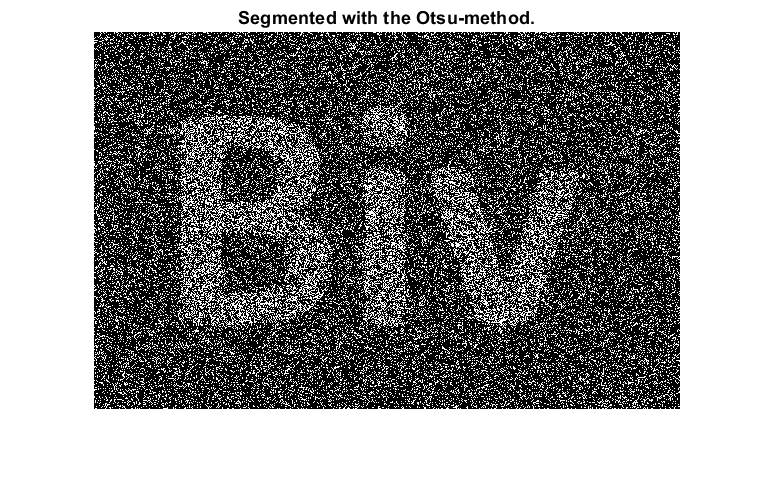

segmented = imbinarize(biv);
imshow(segmented);
title("Segmented with the Otsu-method.");

Es funktioniert nicht, weil das bild nur 2 Farben hat, also bit es keine Sinnvolle Schwellenwert auswahl der das Bild ändert. 

c)

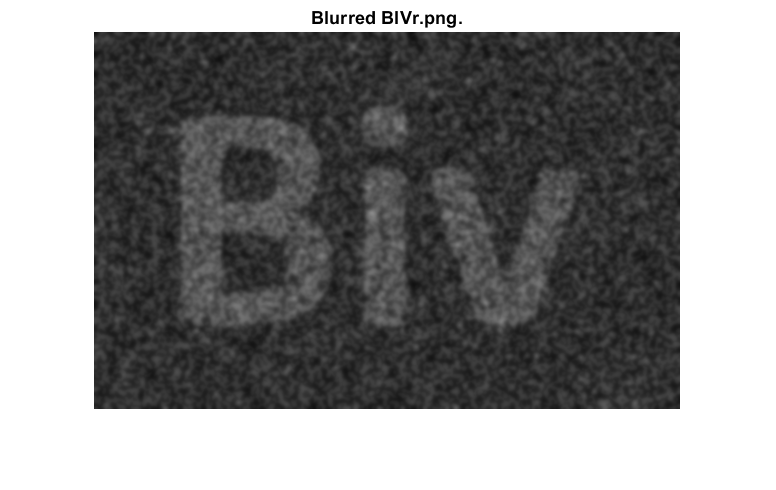

blurredBiv = imgaussfilt(biv);
for c = 1:25
    blurredBiv = imgaussfilt(blurredBiv);
end
imshow(blurredBiv);
title("Blurred BIVr.png.");

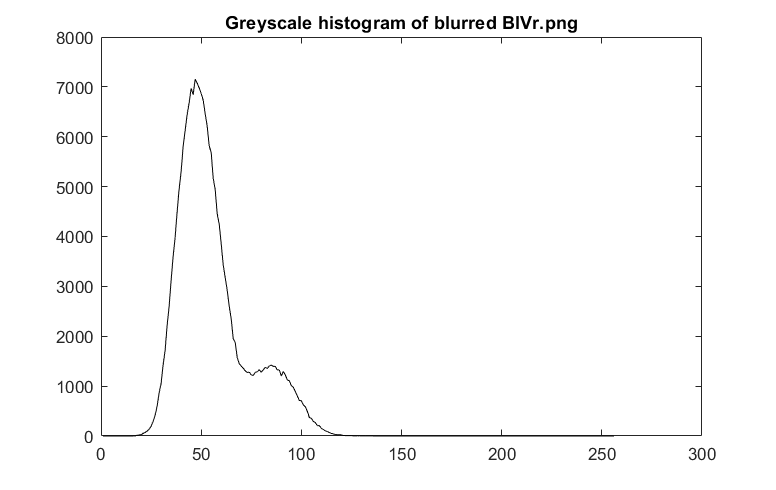

histBlurred = imhist(blurredBiv);
plot(histBlurred, 'k');
title("Greyscale histogram of blurred BIVr.png");

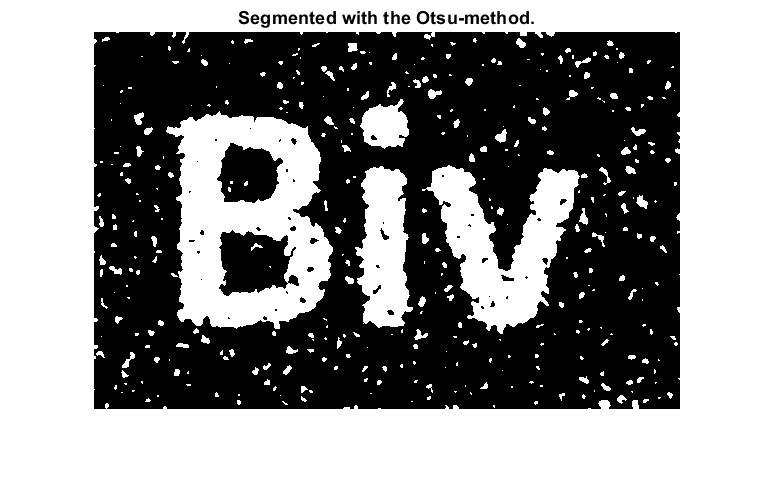

segmentedBlurred = imbinarize(blurredBiv);
imshow(segmentedBlurred);
title("Segmented with the Otsu-method.");

Die Schwellenwert liegt links von der Mitte des Histogramms, zwischen den zwei Gipfeln, aber eher rechts vom Mittelwert der Gipfeln (wo der Tal ist).

d)

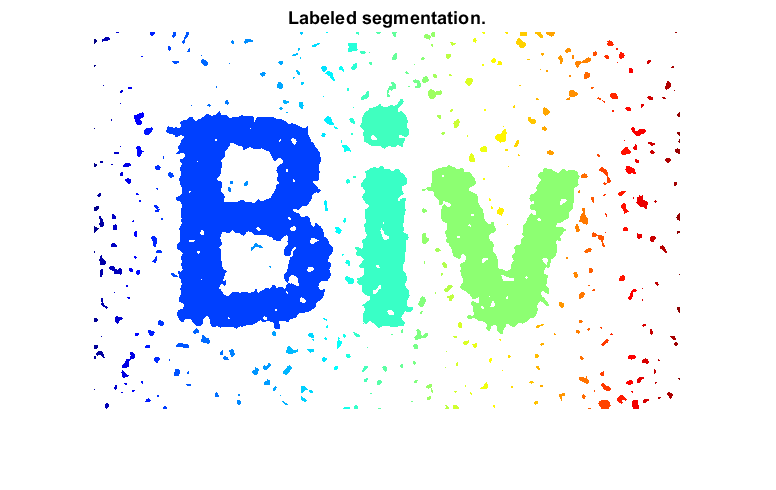

labeled = bwlabel(segmentedBlurred);
labeledRgb = label2rgb(labeled);
imshow(labeledRgb);
title("Labeled segmentation.");

red = labeledRgb(:, :, 1);
green = labeledRgb(:, :, 2);
blue = labeledRgb(:, :, 3);
number = sum(red(:) == 64 & green(:) == 255 & blue(:) == 191)

number = 1649

### 2 Histogrammbasierte Segmentierung nach Korrektur von Shading 

a) 

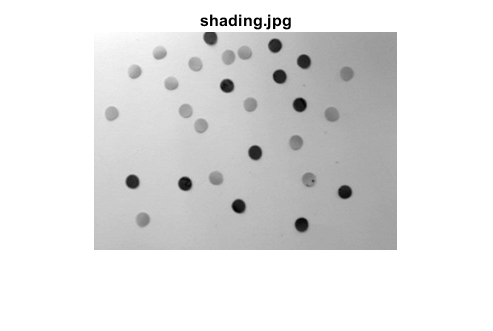

shading = imread("shading.jpg");
shading = shading(:, :, 1);
figure;
imshow(shading, []);
title("shading.jpg");

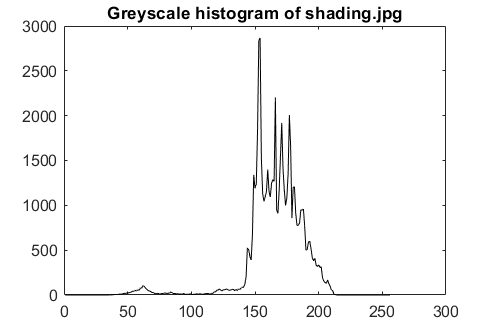

hist = imhist(shading);
plot(hist, 'k');
title("Greyscale histogram of shading.jpg");

thresh1 = graythresh(shading)

thresh1 = 0.4745

thresh2 = multithresh(shading, 2)

thresh2 = 1×2 uint8 row vector
   111   167


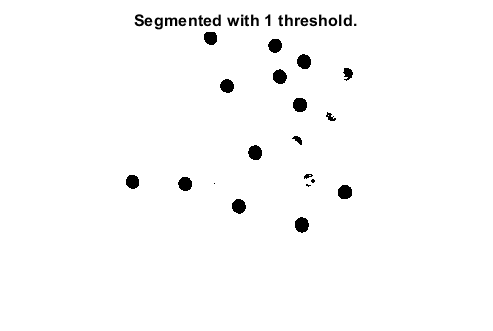

thresh1image = imbinarize(shading, thresh1);
thresh2imageRaw = imquantize(shading, thresh2);
thresh2image = label2rgb(thresh2imageRaw);
imshow(thresh1image);
title("Segmented with 1 threshold.");

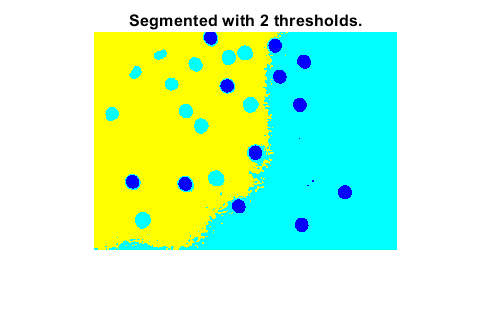

imshow(thresh2image);
title("Segmented with 2 thresholds.");

2 Schwellenwerte. Ohne Angabe 1.

b) Die große Gipfels von 150 bis 200 sind wahrscheinlich das Hintergrund, rechts sind die schwarzr Punkte und links sind die weiße.

c/d/e)

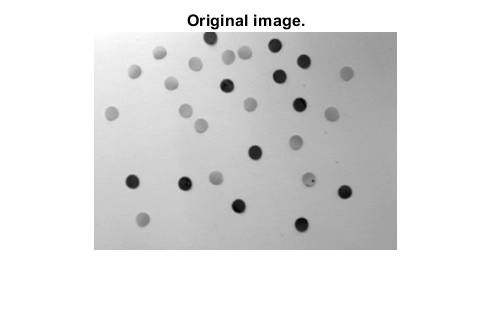

original = rescale(shading);
shade = ordfilt2(original,169,ones(13,13));
imshow(original);
title("Original image.");

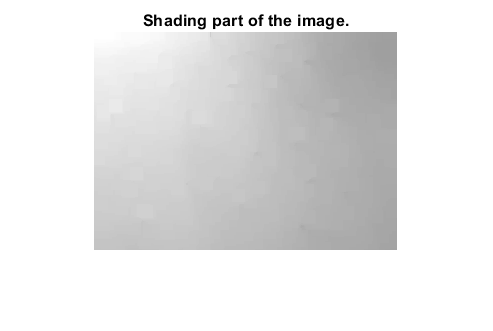

imshow(shade);
title("Shading part of the image.");

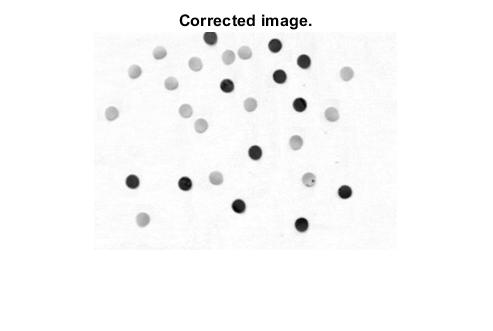

correctedShading = original ./ shade;
imshow(correctedShading);
title("Corrected image.");

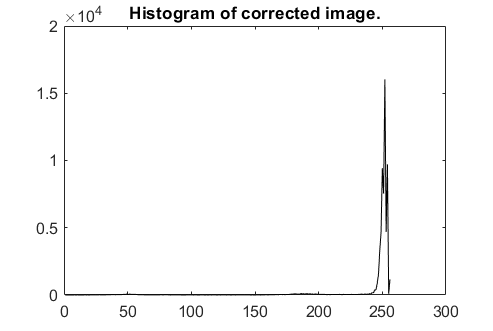

hist = imhist(uint8(correctedShading * 255));
plot(hist, 'k');
title("Histogram of corrected image.");

Es gibt 3 Peaks, die große ist der Hintergrund, die Peaks für die Punkte sind viel viel kleiner weil sie weniger Pixel im Bild besitzen, aber sind viel klarer zu sehen mit Glättung.

f)

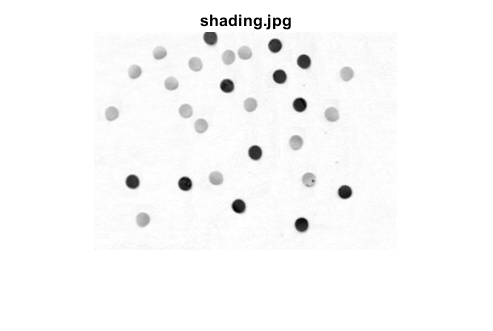

imshow(correctedShading, []);
title("shading.jpg");

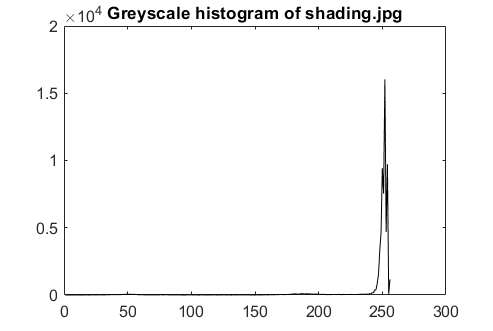

hist = imhist(correctedShading);
plot(hist, 'k');
title("Greyscale histogram of shading.jpg");

thresh1 = graythresh(correctedShading)

thresh1 = 0.6078

thresh2 = multithresh(correctedShading, 2)

thresh2 =     0.4745    0.8549


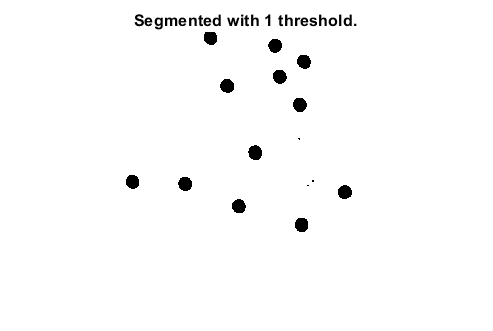

thresh1image = imbinarize(correctedShading, thresh1);
thresh2imageRaw = imquantize(correctedShading, thresh2);
thresh2image = label2rgb(thresh2imageRaw);
imshow(thresh1image);
title("Segmented with 1 threshold.");

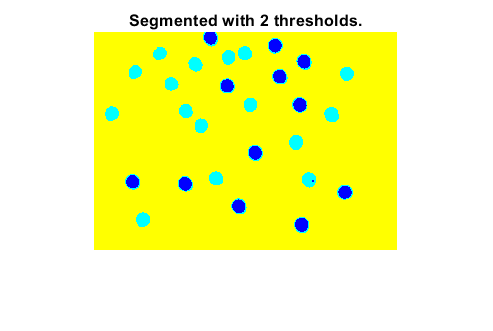

imshow(thresh2image);
title("Segmented with 2 thresholds.");